clc; clear; close all;

% Way-points
p(:, 1) = [2000 500 1600]'/1000;
p(:, 2) = [2000 -500 1600]'/1000;
p(:, 3) = [1600 500 900]'/1000;
p(:, 4) = [1600 0 900]'/1000;
p(:, 5) = [2000 500 1600]'/1000

p =     2.0000    2.0000    1.6000    1.6000    2.0000
    0.5000   -0.5000    0.5000         0    0.5000
    1.6000    1.6000    0.9000    0.9000    1.6000


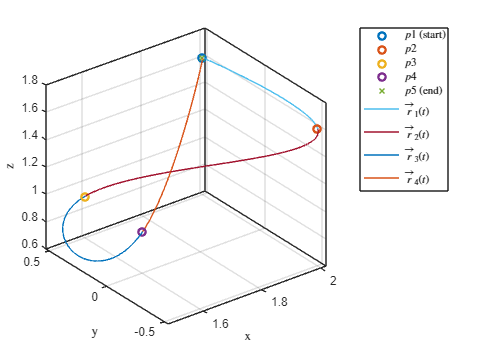

t1 = [0:4];

% Plotting waypoints
fig1 = figure;
plot3(p(1,1), p(2,1), p(3,1), 'o', LineWidth=2)
hold on
grid on
box on
xlabel('x', Interpreter='latex')
ylabel('y', Interpreter='latex')
zlabel('z', Interpreter='latex')
plot3(p(1,2), p(2,2), p(3,2), 'o', LineWidth=2)
plot3(p(1,3), p(2,3), p(3,3), 'o', LineWidth=2)
plot3(p(1,4), p(2,4), p(3,4), 'o', LineWidth=2)
plot3(p(1,5), p(2,5), p(3,5), 'x', LineWidth=1)

% Creating varibles for (x,y,z)-points, to make it more readeble.
xPoints = p(1, :);
yPoints = p(2, :);
zPoints = p(3, :);

% Getting polynomal coefficients
coeffx = getCoeff(t1, xPoints);
coeffy = getCoeff(t1, yPoints);
coeffz = getCoeff(t1, zPoints);

% Extracting coefficients for p1...p4 in x, y and z
p1coeffx = coeffx(1:5);
p1coeffy = coeffy(1:5);
p1coeffz = coeffz(1:5);

p2coeffx = coeffx(6:9);
p2coeffy = coeffy(6:9);
p2coeffz = coeffz(6:9);

p3coeffx = coeffx(10:13);
p3coeffy = coeffy(10:13);
p3coeffz = coeffz(10:13);

p4coeffx = coeffx(14:18);
p4coeffy = coeffy(14:18);
p4coeffz = coeffz(14:18);

% Creating functionhandlers for third and fourth order polinomals
p4 = @(coeff_param, t) coeff_param(1) + coeff_param(2)*t + coeff_param(3)*t.^2 + coeff_param(4)*t.^3 + coeff_param(5)*t.^4;
p3 = @(coeff_param, t) coeff_param(1) + coeff_param(2)*t + coeff_param(3)*t.^2 + coeff_param(4)*t.^3;

% Time for plotting
t1 = 0:0.001:1;
t2 = 1:0.001:2;
t3 = 2:0.001:3;
t4 = 3:0.001:4;

% Plotting the path piecewice
plot3(p4(p1coeffx, t1), p4(p1coeffy, t1), p4(p1coeffz, t1))
plot3(p3(p2coeffx, t2), p3(p2coeffy, t2), p3(p2coeffz, t2))
plot3(p3(p3coeffx, t3), p3(p3coeffy, t3), p3(p3coeffz, t3))
plot3(p4(p4coeffx, t4), p4(p4coeffy, t4), p4(p4coeffz, t4))
legend("$p1$ (start)", "$p2$", "$p3$", "$p4$", "$p5$ (end)", "$\vec{r}_1(t)$", "$\vec{r}_2(t)$", "$\vec{r}_3(t)$", "$\vec{r}_4(t)$", Interpreter='latex')
hold off;

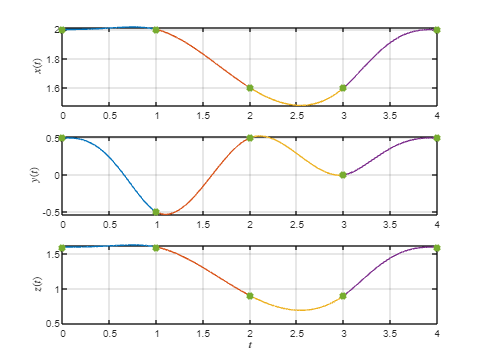


%filename1 = '3d_plot.eps';
%saveas(fig1,filename1, 'epsc');

% Plotting x(t), y(t) and z(t)
fig2 = figure;
t = 0:4;
subplot(3, 1, 1)
plot(t1, p4(p1coeffx, t1))
hold on; grid on;
plot(t2, p3(p2coeffx, t2))
plot(t3, p3(p3coeffx, t3))
plot(t4, p4(p4coeffx, t4))
plot(t, xPoints, 'x', 'LineWidth',3)
ylabel('$x(t)$', Interpreter='latex')

subplot(3, 1, 2)
plot(t1, p4(p1coeffy, t1))
hold on; grid on;
plot(t2, p3(p2coeffy, t2))
plot(t3, p3(p3coeffy, t3))
plot(t4, p4(p4coeffy, t4))
plot(t, yPoints, 'x', 'LineWidth',3)
ylabel('$y(t)$', Interpreter='latex')

subplot(3, 1, 3)
plot(t1, p4(p1coeffz, t1))
hold on; grid on;
plot(t2, p3(p2coeffz, t2))
plot(t3, p3(p3coeffz, t3))
plot(t4, p4(p4coeffz, t4))
plot(t, zPoints, 'x', 'LineWidth',3)
xlabel('$t$', Interpreter='latex')
ylabel('$z(t)$', Interpreter='latex')

hold off

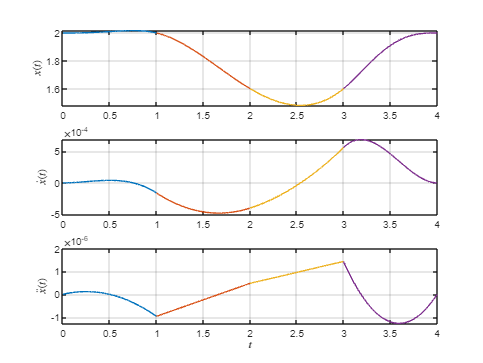

%plotting x, xdot, xdotdot

fig3 = figure;

t = 0:4;
subplot(3, 1, 1)
plot(t1, p4(p1coeffx, t1))
hold on; grid on;
plot(t2, p3(p2coeffx, t2))
plot(t3, p3(p3coeffx, t3))
plot(t4, p4(p4coeffx, t4))
ylabel('$x(t)$', Interpreter='latex')

subplot(3, 1, 2)
plot(t1(1:(end-1)), diff(p4(p1coeffx, t1)))
hold on; grid on;
plot(t2(1:(end-1)), diff(p3(p2coeffx, t2)))
plot(t3(1:(end-1)), diff(p3(p3coeffx, t3)))
plot(t4(1:(end-1)), diff(p4(p4coeffx, t4)))
ylabel('$\dot{x}(t)$', Interpreter='latex')

subplot(3, 1, 3)
plot(t1(1:(end-2)), diff(p4(p1coeffx, t1), 2))
hold on; grid on;
plot(t2(1:(end-2)), diff(p3(p2coeffx, t2), 2))
plot(t3(1:(end-2)), diff(p3(p3coeffx, t3), 2))
plot(t4(1:(end-2)), diff(p4(p4coeffx, t4), 2))
ylabel('$\dot{x}(t)$', Interpreter='latex')
xlabel('$t$', Interpreter='latex')
ylabel('$\ddot{x}(t)$', Interpreter='latex')


filename1 = 'plt_x.eps';
%saveas(fig3,filename1, 'epsc');

function [coeff] = getCoeff(t, p)
A = zeros(18, 18);
B = zeros(18,1);

A(1, 1:5) = F4(t(1));
A(2, 1:5) = F4Dot(t(1));
A(3, 1:5) = F4DotDot(t(1));
A(4, 1:5) = F4(t(2));
A(5, 1:5) = F4(t(2));
A(6, 1:5) = F4Dot(t(2));
A(7, 1:5) = F4DotDot(t(2));

A(5, 6:9) = -F3(t(2));
A(6, 6:9) = -F3Dot(t(2));
A(7, 6:9) = -F3DotDot(t(2));
A(8, 6:9) = F3(t(3));
A(9, 6:9) = F3(t(3));
A(10, 6:9) = F3Dot(t(3));
A(11, 6:9) = F3DotDot(t(3));

A(9, 10:13) = -F3(t(3));
A(10, 10:13) = -F3Dot(t(3));
A(11, 10:13) = -F3DotDot(t(3));
A(12, 10:13) = F3(t(4));
A(13, 10:13) = F3(t(4));
A(14, 10:13) = F3Dot(t(4));
A(15, 10:13) = F3DotDot(t(4));

A(13, 14:18) = -F4(t(4));
A(14, 14:18) = -F4Dot(t(4));
A(15, 14:18) = -F4DotDot(t(4));
A(16, 14:18) = F4(t(5));
A(17, 14:18) = F4Dot(t(5));
A(18, 14:18) = F4DotDot(t(5));

B(1) = p(1);
B(4) = p(2);
B(8) = p(3);
B(12) = p(4);
B(16) = p(5);

coeff = A\B;

end



function output = F4(t)
output = [1 t t.^2 t.^3 t.^4];
end

function output = F4Dot(t)
output = [0 1 2*t 3*t^2 4*t^3];
end

function output = F4DotDot(t)
output = [0 0 2 6*t 12*t^2];
end
function output = F3(t)
output = [1 t t^2 t^3];
end

function output = F3Dot(t)
output = [0 1 2*t 3*t^2];
end

function output = F3DotDot(t)
output = [0 0 2 6*t];
end